2. El modelo de Lorenz, fue propuesto en 1963 por Edward Lorenz como un modelo simplificado de convección atmosférica.


$$\dot x_1 = \sigma (x_2 - x_1)\\
\dot x_2 = x_1 (\rho - x_3) - x_2\\
\dot x_3 = x_1 x_2 - \beta x_3\\
\sigma,\rho,\beta \in \mathbb{R}^+$$


Para los valores $\sigma =10,\beta =8/3,\rho =28$ el sistema exhibe soluciones caóticas; para casi todas las condiciones iniciales el sistema converge a un conjunto invariante conocido con el nombre de Atractor de Lorentz.

a) Utilizar tanto Matlab como Simulink para simular el modelo de Lorenz. Emplear para ello los parámetros indicados más arriba.

Establecemos el valor de los parámetros indicados y definimos el sistema (ver final del documento).

[sigma, beta, rho] = deal(10, 8/3, 28);

Para estudiar el sistema, representaremos una trayectoria en el espacio de fases.

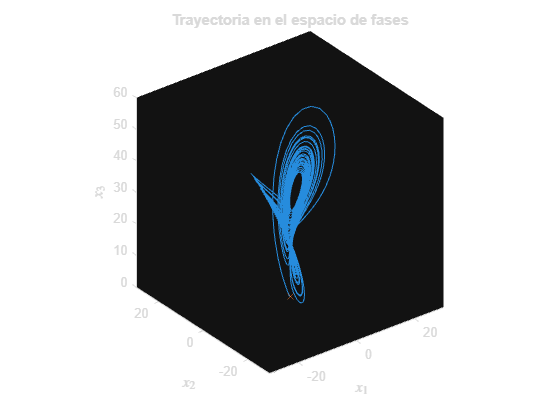

x0 = [0.1; 0.1; 0.1];
t_range = [0, 50];

[t,x] = ode45(@(t,x)lorentz(t,x,sigma,beta,rho), t_range, x0);

figure(1)
clf
plot3(x(:,1), x(:,2), x(:,3))
hold on
plot3(x0(1,1), x0(2,1), x0(3,1), 'x')
title('Trayectoria en el espacio de fases')
xlabel('$x_1$', 'interpreter', 'latex')
ylabel('$x_2$', 'interpreter', 'latex')
zlabel('$x_3$', 'interpreter', 'latex')
xlim([-30, 30])
ylim([-30, 30])
zlim([0, 60])
daspect([1 1 1])

b) Comprobar mediante simulación, que para $\rho <1$, el sistema converge a su único punto de equilibrio. Para $\rho =1$ el sistema sufre una bifurcación de horquilla. Obtener los puntos de equilibrio del sistema y comprobarlo.

Comprobamos la estabilidad para $\rho <1$.

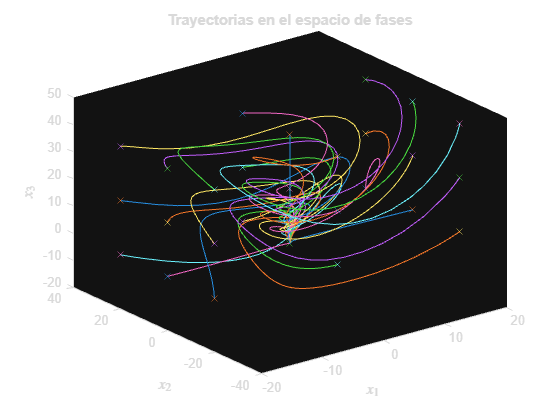

x1 = -20:20:20;
x2 = -20:20:20;
x3 = 0:20:40;
t_range = [0,5];
rho = 0.5;

figure(2)
clf
axis equal
for i = 1:length(x1)
    for j = 1:length(x2)
        for k = 1:length(x3)
            [t,x] = ode45(@(t,x)lorentz(t,x,sigma,beta,rho),t_range,[x1(i);x2(j);x3(k)]);
            plot3(x(:,1), x(:,2), x(:,3))
            hold on
            plot3(x1(i), x2(j), x3(k), 'x')
            clear x t
        end
    end
end
title('Trayectorias en el espacio de fases')
xlabel('$x_1$', 'interpreter', 'latex')
ylabel('$x_2$', 'interpreter', 'latex')
zlabel('$x_3$', 'interpreter', 'latex')

Y ahora con $\rho =1$.

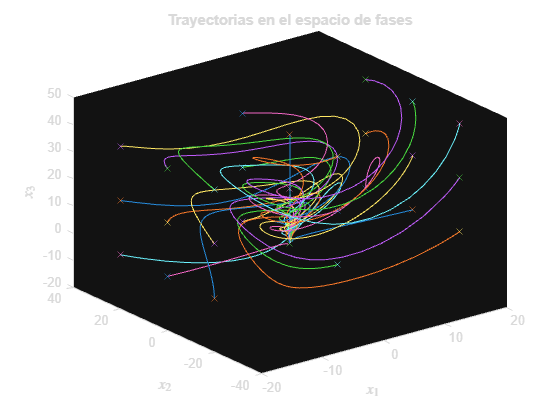

rho = 1;

figure(3)
clf
axis equal
for i = 1:length(x1)
    for j = 1:length(x2)
        for k = 1:length(x3)
            [t,x] = ode45(@(t,x)lorentz(t,x,sigma,beta,rho),t_range,[x1(i);x2(j);x3(k)]);
            plot3(x(:,1), x(:,2), x(:,3))
            hold on
            plot3(x1(i), x2(j), x3(k), 'x')
            clear x t
        end
    end
end
title('Trayectorias en el espacio de fases')
xlabel('$x_1$', 'interpreter', 'latex')
ylabel('$x_2$', 'interpreter', 'latex')
zlabel('$x_3$', 'interpreter', 'latex')

function xdot = lorentz(t, x, sigma, beta, rho)
    xdot(1,1) = sigma * (x(2,1) - x(1,1));
    xdot(2,1) = x(1,1) * (rho - x(3,1)) - x(2,1);
    xdot(3,1) = x(1,1) * x(2,1) - beta * x(3,1);
end